clear; clc;
close all;
addpath('../functions', '../data')

% Load data
load proj23.mat
t_org= ElGeneina.rain_org_t;
ndvi = ElGeneina.nvdi;
% rescale the vegitation data so it is between -1 and 1
rendvi = (ndvi/255)*2 -1;
y = log(rendvi);
t_ndvi = ElGeneina.nvdi_t;

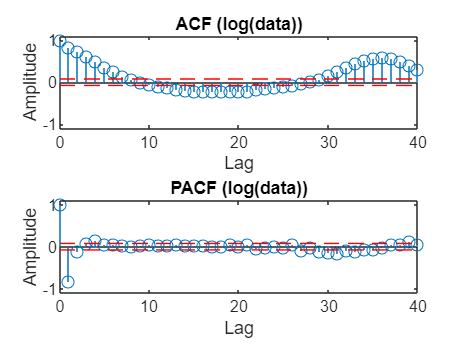

plotACFnPACF(y,40,'log(data)');

% make a model for vegetation
A0 = [1 1];
C0 = [1 0.2 zeros(1,32) 0.2 0.4 0.3] ;
poly = idpoly(A0,[],C0);
poly.Structure.a.Free = A0;
poly.Structure.c.Free = C0;
model = pem(y,poly);
e_res = filter(model.a,model.c,y);
plotACFnPACF(e_res,40,'residual');
checkIfWhite(e_res);

The residual is deemed to be WHITE according to the Monti-test (as 13.68 < 31.41).


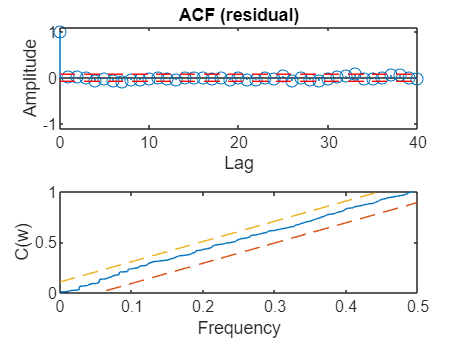

Whiteness test with 5% significance
  Ljung-Box-Pierce test: 1 (white if 13.70 < 36.42)
  McLeod-Li test:        1 (white if 17.54 < 36.42)
  Monti test:            1 (white if 17.63 < 36.42)
  Sign change test:      0 (white if 0.45 in [0.46,0.54])


whitenessTest(e_res)

A0 = model.a;
C0 = model.c;
ord = 5; % model order/ state vector dimension 

N = length(y);
A     = eye(ord);
Rw    = 0.1;                                      % Measurement noise covariance matrix, R_w. Note that Rw has the same dimension as Ry.
Re    = 1e-5*eye(ord);                        % System noise covariance matrix, R_e. Note that Re has the same dimension as Rx_t1.

Rx_t1 = eye(ord);                             % Initial covariance matrix, V0 = R_{1|0}^{x,x}
h_et  = zeros(N,1);                             % Estimated one-step prediction error.
xt    = zeros(ord,N);                         % Estimated states. Intial state, x_{1|0} = 0.
yhat  = zeros(N,1);                             % Estimated output.
xStd  = zeros(ord,N);                         % Stores one std for the one-step prediction.

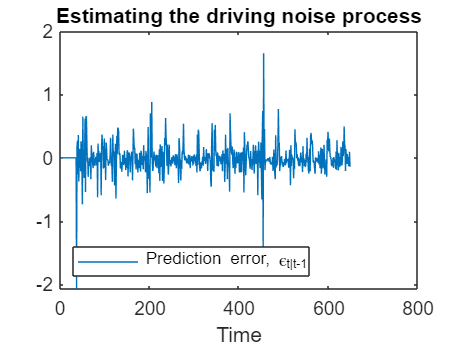

for t=37:N                                      % We use t-36, so start at t=37.
    % Update the predicted state and the time-varying state vector.
    x_t1 = A*xt(:,t-1);                         % x_{t|t-1} = A x_{t-1|t-1}
   
    C    = [ -y(t-1) h_et(t-1) h_et(t-34) h_et(t-35) h_et(t-36)];     % Use earlier prediction errors as estimate of e_t.
    
    % Update the parameter estimates.
    Ry = C*Rx_t1*C' + Rw;                       % R_{t|t-1}^{y,y} = C R_{t|t-1}^{x,x} + Rw
    Kt = Rx_t1*C'/Ry;                           % K_t = R^{x,x}_{t|t-1} C^T inv( R_{t|t-1}^{y,y} )
    yhat(t) = C*x_t1;                           % One-step prediction, \hat{y}_{t|t-1}.
    h_et(t) = y(t)-yhat(t);                     % One-step prediction error, \hat{e}_t = y_t - \hat{y}_{t|t-1}
    xt(:,t) = x_t1 + Kt*( h_et(t) );            % x_{t|t}= x_{t|t-1} + K_t ( y_t - Cx_{t|t-1} ) 

    % Update the covariance matrix estimates.
    Rx_t  = Rx_t1 - Kt*Ry*Kt';                  % R^{x,x}_{t|t} = R^{x,x}_{t|t-1} - K_t R_{t|t-1}^{y,y} K_t^T
    Rx_t1 = A*Rx_t*A' + Re;                     % R^{x,x}_{t+1|t} = A R^{x,x}_{t|t} A^T + Re

    % Estimate a one std confidence interval of the estimated parameters.
    % This is only for the plots.
    xStd(:,t) = sqrt( diag(Rx_t) );            % This is one std for each of the parameters for the one-step prediction.
end

% Examine the estimate of the driving noise.
figure
plot( [h_et])
xlabel('Time')
title('Estimating the driving noise process')
legend( 'Prediction error, \epsilon_{t|t-1}', 'Location','SW')

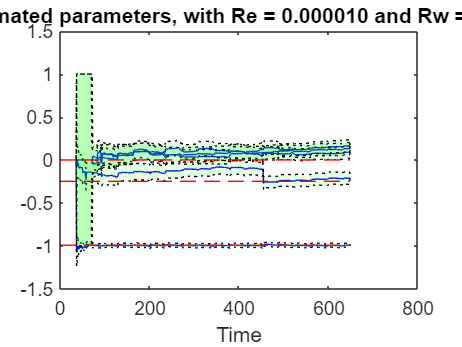

%% Examine the estimated parameters.
% As with the command present, the precision is given with +/- one std. 
trueParams = [A0(2) C0(2) C0(4)];               % These are the true parameters we seek.
figure
plotWithConf( (1:N), xt', xStd', trueParams );
title(sprintf('Estimated parameters, with Re = %7.6f and Rw = %4.3f', Re(1,1), Rw(1,1)))
xlabel('Time')
ylim([-1.5 1.5])


% Examine the final predicted parameters.
fprintf('The final values of the estimated parameters are:\n')

The final values of the estimated parameters are:


for k=1:length(trueParams)
    fprintf('  True value: %5.2f, estimated value: %5.2f (+/- %5.4f).\n', trueParams(k), xt(k,end), xStd(k,end) )
end 

  True value: -0.99, estimated value: -0.99 (+/- 0.0243).
  True value: -0.25, estimated value: -0.21 (+/- 0.0723).
  True value:  0.00, estimated value:  0.09 (+/- 0.0713).


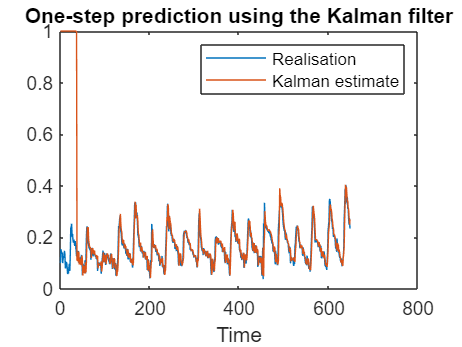

figure
plot( [exp(y) exp(yhat)] )
title('One-step prediction using the Kalman filter')
xlabel('Time')
legend('Realisation', 'Kalman estimate', 'Location','NE')

% K step prediction
%% Estimate the unknown parameters using a Kalman filter and form the k-step prediction.
k  = 7;                                         % k-step prediction.
p0 = 1;                                         % Number of unknowns in the A polynomial (note: this is only the non-zero parameters!).
q0 = 4;                                         % Number of unknowns in the C polynomial (note: this is only the non-zero parameters!).

A     = eye(p0+q0);
Rw    = 0.01;                                      % Measurement noise covariance matrix, R_w. Note that Rw has the same dimension as Ry.
Re    = 10^(-5)*eye(p0+q0);                        % System noise covariance matrix, R_e. Note that Re has the same dimension as Rx_t1.
Rx_t1 = eye(p0+q0);                             % Initial covariance matrix, R_{1|0}^{x,x}
Rx_k  = Rx_t1;
h_et  = zeros(N,1);                             % Estimated one-step prediction error.
xt    = zeros(p0+q0,N-k);                       % Estimated states. Intial state, x_{1|0} = 0.
yhat  = zeros(N-k,1);                           % Estimated output.
yhatk = zeros(N,1);                           % Estimated k-step prediction.

xStd  = zeros(p0+q0,N-k);                       % Stores one std for the one-step prediction.
xStdk = zeros(p0+q0,N-k);  % Stores one std for the k-step prediction.

for t=37:N-k                                     % We use t-36, so start at t=37. As we form a k-step prediction, end the loop at N-k.
    % Update the predicted state and the time-varying state vector.
    x_t1 = A*xt(:,t-1);                         % x_{t|t-1} = A x_{t-1|t-1}
    C    = [ -y(t-1) h_et(t-1) h_et(t-34) h_et(t-35) h_et(t-36)];     % C_{t|t-1}
    
    % Update the parameter estimates.
    Ry = C*Rx_t1*C' + Rw;                       % R_{t|t-1}^{y,y} = C R_{t|t-1}^{x,x} + Rw
    Kt = Rx_t1*C'/Ry;                           % K_t = R^{x,x}_{t|t-1} C^T inv( R_{t|t-1}^{y,y} )
    yhat(t) = C*x_t1;                           % One-step prediction, \hat{y}_{t|t-1}.
    h_et(t) = y(t)-yhat(t);                     % One-step prediction error, \hat{e}_t = y_t - \hat{y}_{t|t-1}
    xt(:,t) = x_t1 + Kt*( h_et(t) );            % x_{t|t}= x_{t|t-1} + K_t ( y_t - Cx_{t|t-1} ) 

    % Update the covariance matrix estimates.
    Rx_t  = Rx_t1 - Kt*Ry*Kt';                  % R^{x,x}_{t|t} = R^{x,x}_{t|t-1} - K_t R_{t|t-1}^{y,y} K_t^T
    Rx_t1 = A*Rx_t*A' + Re;                     % R^{x,x}_{t+1|t} = A R^{x,x}_{t|t} A^T + Re

    % Form the k-step prediction by first constructing the future C vector
    % and the one-step prediction. Note that this is not yhat(t) above, as
    % this is \hat{y}_{t|t-1}.

    y_f = zeros(k,1);
    
    Ck = [ -y(t-1+1) h_et(t-1+1) h_et(t-34+1) h_et(t-35+1) h_et(t-36+1)];           % C_{t+1|t}
    yk = Ck*A*xt(:,t);                            % \hat{y}_{t+1|t} = C_{t+1|t} A x_{t|t}
    y_f(1)= yk;
    
    for r= 2:k
        Cr = [y_f(r-1) h_et(t-1+r) h_et(t-34+r) h_et(t-35+r) h_et(t-36+r)];
        y_f(r)= Cr*A.^r*xt(:,t);
    end
    yhatk(t+k)= y_f(k);

                          % Note that this should be stored at t+k.

    % Estimate a one std confidence interval of the estimated parameters.
    xStd(:,t) = sqrt( diag(Rx_t) );             % This is one std for each of the parameters for the one-step prediction.
end
length(yhatk)

ans = 648

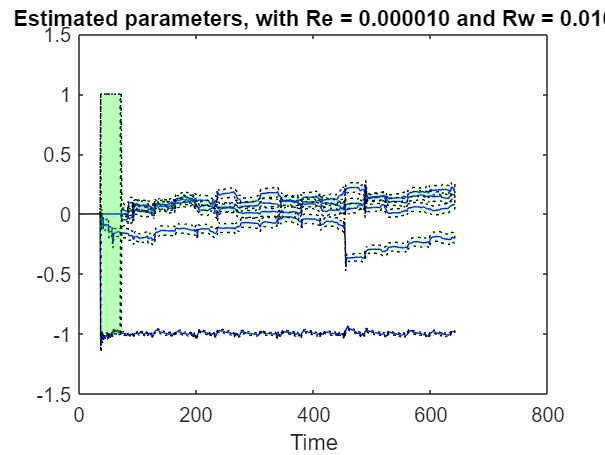

%% Examine the estimated parameters.
% If you examine the confidence interval for the k-step prediction, you
% will find that this is very close to the one-step prediction for these
% settings (use xStdk). Why is that?

figure
plotWithConf( (1:N-k), xt', xStd');
title(sprintf('Estimated parameters, with Re = %7.6f and Rw = %4.3f', Re(1,1), Rw(1,1)))
xlabel('Time')
ylim([-1.5 1.5])

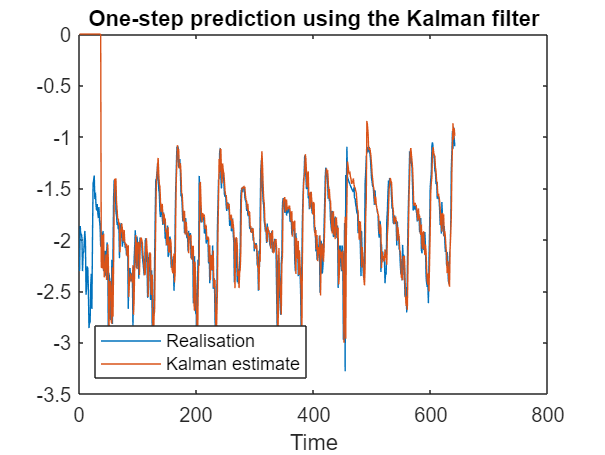

%% Show the one-step prediction. 
figure
plot( [y(1:N-k) yhat] )
title('One-step prediction using the Kalman filter')
xlabel('Time')
legend('Realisation', 'Kalman estimate', 'Location','SW')

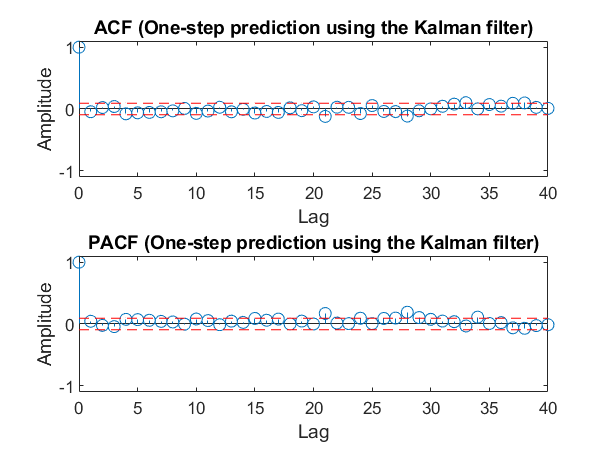

e1 = y(200:N-k)-yhat(200:end);                   % Ignore the initial values to let the filter converge first.
plotACFnPACF( e1, 40, 'One-step prediction using the Kalman filter');

fprintf('Examining the one-step residual.\n')

Examining the one-step residual.


checkIfWhite( e1 );

The residual is deemed to be WHITE according to the Monti-test (as 24.72 < 31.41).


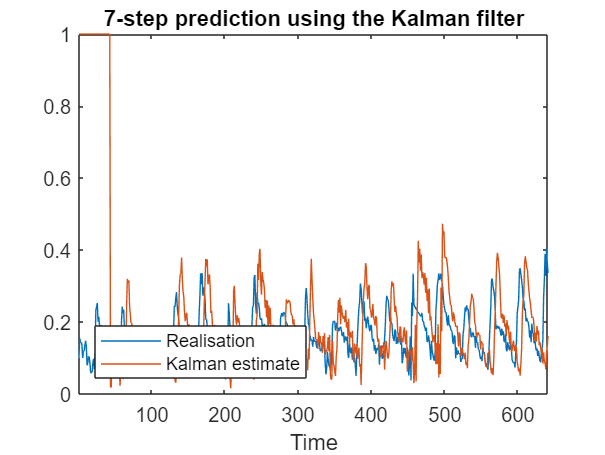

%% Show the k-step prediction. 
figure
plot( [exp(y) exp(yhatk)] )
title( sprintf('%i-step prediction using the Kalman filter', k) )
xlabel('Time')
legend('Realisation', 'Kalman estimate', 'Location','SW')
xlim([1 N-k])

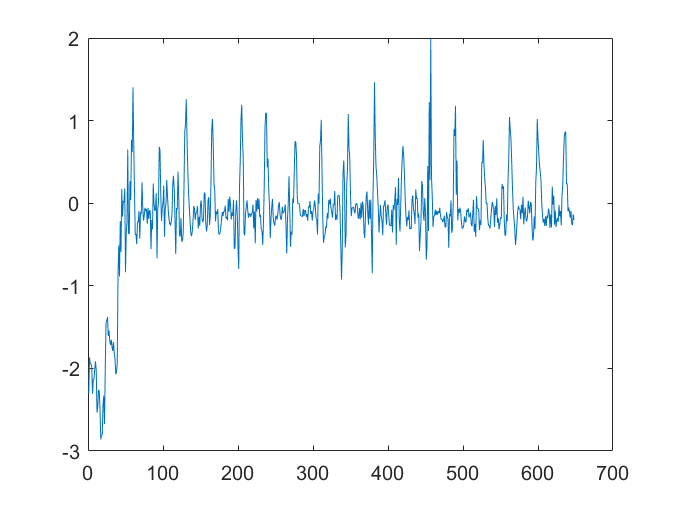

figure
plot(y-yhatk)

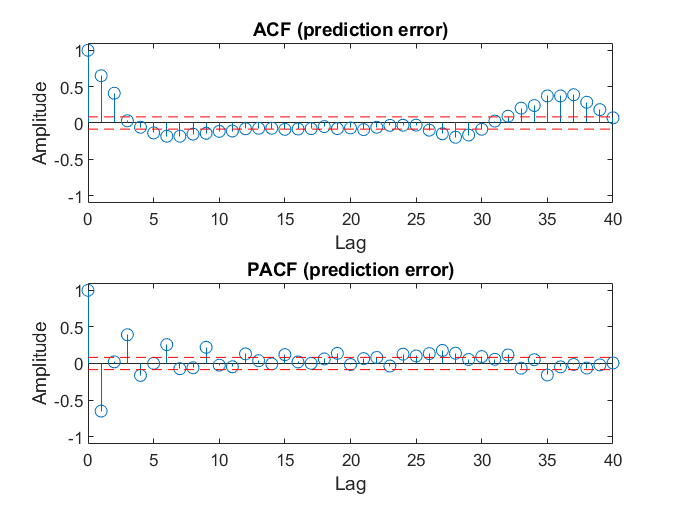

ans =     1.0000
    0.6502
    0.4097
    0.0308
   -0.0583
   -0.1359
   -0.1815
   -0.1812
   -0.1526
   -0.1413


pred_e = y-yhatk;
plotACFnPACF(pred_e(100:end),40,'prediction error')

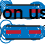

%% Examine k-step prediction residual.
ek = y(N-200:N-k)-yhatk(N-200:N-k);             % Ignore the initial values to let the filter converge first.
plotACFnPACF( ek, 40, sprintf('%i-step prediction using the Kalman filter', k)  );


fprintf('  The variance of original signal is                %5.2f.\n', var(y)')

  The variance of original signal is                 0.16.


fprintf('  The variance of the 1-step prediction residual is %5.2f.\n', var(e1)')

  The variance of the 1-step prediction residual is  0.05.


fprintf('  The variance of the %i-step prediction residual is %5.2f.\n', k, var(ek)')

  The variance of the 5-step prediction residual is  0.31.
